# Detect Lines in Images Using Hough

This example shows how to detect lines in an image using the H`ough` transform.

Read an image into the workspace and, to make this example more illustrative, rotate the image. Display the image.

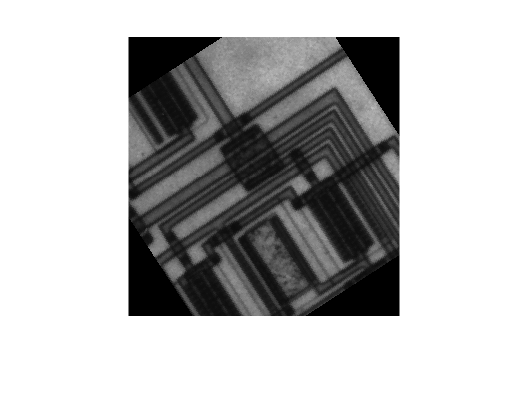

I = imread('circuit.tif');
rotI = imrotate(I,33,'crop');
imshow(rotI)

Find the edges in the image using the `edge` function. 

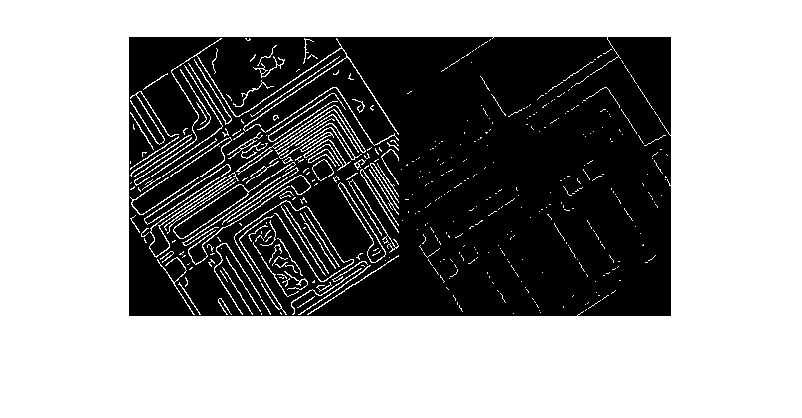

BW_canny = edge(rotI,'canny',0.1);
BW_sobel = edge(rotI,'sobel',0.1);
BW_prewitt = edge(rotI,'prewitt',0.1);
BW_roberts = edge(rotI,'roberts',0.1);
imshowpair(BW_canny,BW_sobel,'montage');

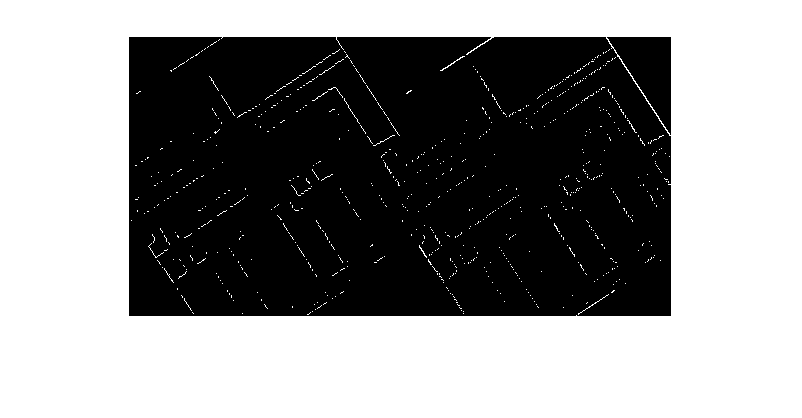

imshowpair(BW_prewitt,BW_roberts,'montage');

Compute the Hough transform of the binary image returned by `edge`.

[H,theta,rho] = hough(BW)

H =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

theta =    -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51   -50   -49   -48   -47   -46   -45   -44   -43   -42   -41


rho =   -389  -388  -387  -386  -385  -384  -383  -382  -381  -380  -379  -378  -377  -376  -375  -374  -373  -372  -371  -370  -369  -368  -367  -366  -365  -364  -363  -362  -361  -360  -359  -358  -357  -356  -355  -354  -353  -352  -351  -350  -349  -348  -347  -346  -345  -344  -343  -342  -341  -340


Display the transform, `H`, returned by the `hough` function.

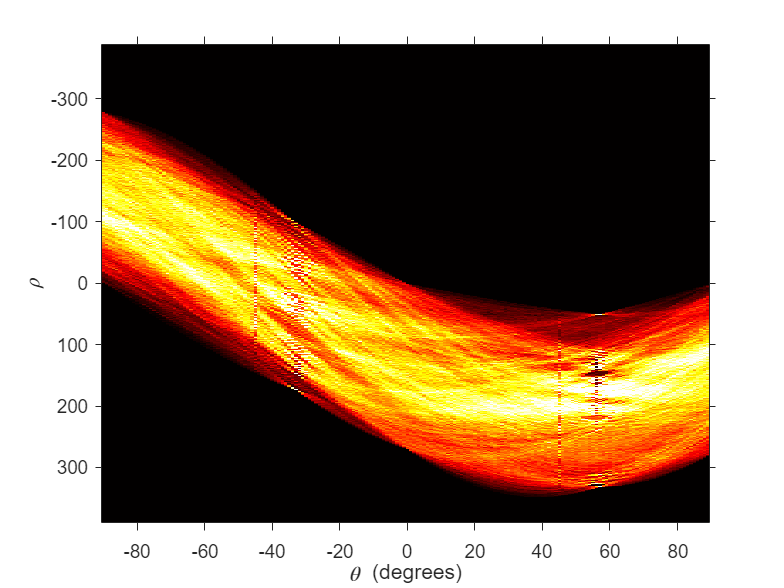

figure
imshow(imadjust(rescale(H)),[],...
       'XData',theta,...
       'YData',rho,...
       'InitialMagnification','fit');
xlabel('\theta (degrees)')
ylabel('\rho')
axis on
axis normal 
hold on
colormap(gca,hot)

Find the peaks in the Hough transform matrix, `H`, using the `houghpeaks` function.

P = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))))

P =    524   147
   564   147
   550   147
   425    58
   592   147


Superimpose a plot on the image of the transform that identifies the peaks.

在变换的图像上叠加一个图，以确定峰值。

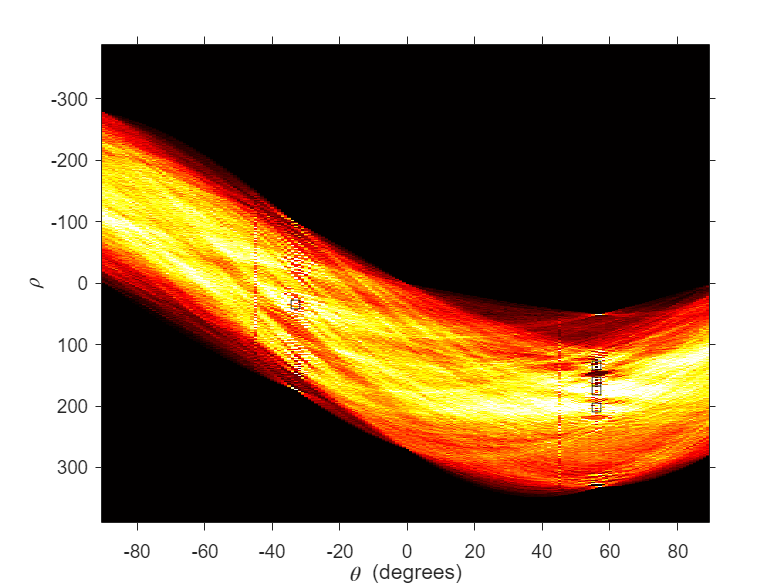

x = theta(P(:,2));
y = rho(P(:,1));
plot(x,y,'s','color','black');

Find lines in the image using the `houghlines` function. 

lines = houghlines(BW,theta,rho,P,'FillGap',5,'MinLength',7)

lines = 1×16 struct array with fields:
    point1
    point2
    theta
    rho


Create a plot that displays the original image with the lines superimposed on it.

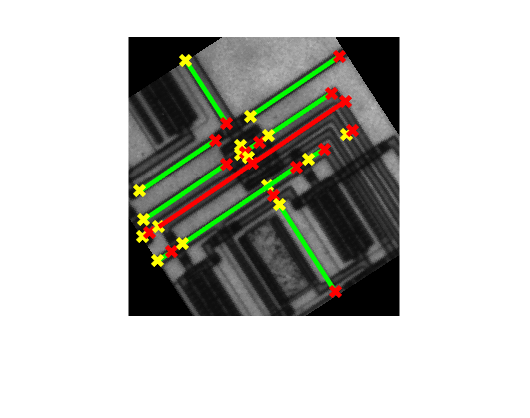

figure, imshow(rotI), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end
% highlight the longest line segment
plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','red');

*Copyright 2012 The MathWorks, Inc.*